N = 5000;                 % Number of samples
t = linspace(0,5,N)';    % Time vector

%% Desired signal (ideal)
s = sawtooth(2*pi*2*t(1:N,1), 0.5);   % Sawtooth signal (width=0.5)

%% Noise (non-stationary: 50 Hz then 100 Hz + WGN)
phi = pi/4; % Phase shift
n1 = 0.2*sin(2*pi*50*t(1:N/2,1) - phi);
n2 = 0.3*sin(2*pi*100*t(N/2+1:N,1) - phi);
nwg = s - awgn(s, 10, 'measured');
eta = [n1;n2];
noise = eta + nwg;

x = s + noise;
r_n = 0.3 * (nwg + sin(2*pi*50*t + pi/6) + sin(2*pi*100*t + pi/4));
%% LMS adaptive filter
M_lms = 21;             % Filter order
mu = 0.01;         % Step size (try different values)
K = M_lms +1;
w = zeros(K,1);     % Initial weights
N1 = length(x)

N1 = 5000

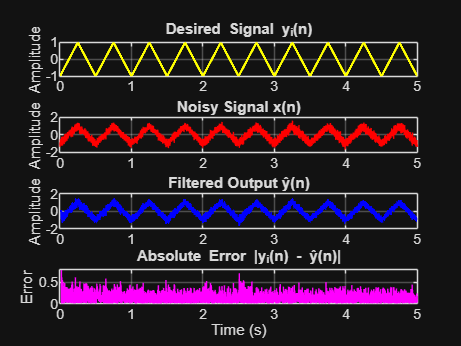


y_hat = zeros(N1,1); 
e = zeros(N1,1);     % Error = Filtered output

for n = K:N1
    x_vec = r_n(n:-1:n-K+1);       % input vector [x(n), x(n-1), ...]
    y(n) = w'*x_vec;         % filter output
    e(n) = x(n)-y(n);     % error
    w = w + 2*mu*e(n)*x_vec;     % weight update
end


%% Absolute error
abs_err = abs(s - e);

figure;
subplot(4,1,1);
plot(t, s, 'y','LineWidth',1.5); grid on;
title('Desired Signal y_i(n)'); ylabel('Amplitude');

subplot(4,1,2);
plot(t, x, 'r'); grid on;
title('Noisy Signal x(n)'); ylabel('Amplitude');


subplot(4,1,3);
plot(t, e, 'b','LineWidth',1.2); grid on;
title('Filtered Output ŷ(n)'); ylabel('Amplitude');

subplot(4,1,4);
plot(t, abs_err, 'm'); grid on;
title('Absolute Error |y_i(n) - ŷ(n)|');
xlabel('Time (s)'); ylabel('Error');
ylim([0 0.8]);



mu_values = [0.0005, 0.001, 0.01];
M_values = [10, 20, 50];
mse_results = zeros(length(mu_values), length(M_values));

for i = 1:length(mu_values)
    for j = 1:length(M_values)
        mu = mu_values(i);
        M = M_values(j);
        K = M+1;
        w = zeros(K,1);
        y_hat = zeros(N,1);
        for n = K:N
            x_vec = r_n(n:-1:n-K+1);
            y_hat(n) = w'*x_vec;
            e(n) = x(n) - y_hat(n);
            w = w + 2*mu*e(n)*x_vec;
        end
        mse_results(i,j) = mean((s - e).^2);
    end
end

disp('MSE results (rows=mu, cols=M):');

MSE results (rows=mu, cols=M):


disp(mse_results);

    0.0558    0.0495    0.0425
    0.0520    0.0434    0.0385
    0.0379    0.0298    0.0294

